# Wprowadzenie do systemu algebry komputerowej Matlab

Systemy algebry komputerowej "rozumieją" wyrażenia matematyczne i potrafią wykonywać z ich użyciem operacje, m.in. takie jak:

- rozwiazywanie równań i nierówności

- znajdowanie granic i sum szeregów

- wyznaczanie pochodnych i całek

## Definiowanie zmiennych symbolicznych

Aby zdefiniować zmienne jako symbole matematyczne należy użyć polecenia [syms](https://www.mathworks.com/help/symbolic/syms.html) z zestawu narzędzi [Symbolic Math Toolbox](https://www.mathworks.com/help/symbolic/index.html?s_tid=CRUX_lftnav). Poniżej zadeklarowano jako symbole zmienne x, a, b oraz c.

syms x a b c

Od momentu deklaracji możliwe jest wykorzystanie zmiennych do przekształceń symbolicznych. Np. co definiowania wyrażeń:

w1 = ((x+c)*(c+b))^2

$$w1 = {\left(b+c\right)}^{2}\,{\left(c+x\right)}^{2}$$

w2 = ((x-a)*(1:10)).^2

$$w2 = \left(\begin{array}{cccccccccc} {\left(a-x\right)}^{2} & {\left(2\,a-2\,x\right)}^{2} & {\left(3\,a-3\,x\right)}^{2} & {\left(4\,a-4\,x\right)}^{2} & {\left(5\,a-5\,x\right)}^{2} & {\left(6\,a-6\,x\right)}^{2} & {\left(7\,a-7\,x\right)}^{2} & {\left(8\,a-8\,x\right)}^{2} & {\left(9\,a-9\,x\right)}^{2} & {\left(10\,a-10\,x\right)}^{2} \end{array}\right)$$

Aby zdefiniować funkcję należy postępować analogicznie. W przypadku funkcji konieczne jest wyszczególnienie argumentów przyjmowanych przez funkcję oraz zdefiniowanie wyrażenia opisującego funkcję $f\left(x\right)=3x^2 {\cdot e}^x \cdot \sin \left(x\right)$:

syms f(x) % definicja symbolu f(x) jako funkcji symbolicznej
f(x) = 3*x^2 * exp(x) * sin(x) % definicja wyrażenia opisującego funkcję

$$f(x) = 3\,x^{2}\,{\mathrm{e}}^{x}\,\sin\left(x\right)$$

Poniżej wykorzystano funkcję [fplot()](https://www.mathworks.com/help/matlab/ref/fplot.html) do narysowania wykresu.

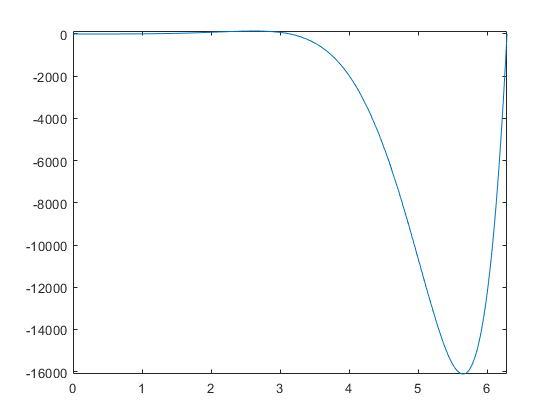

fplot(f(x),[0,2*pi])

Funkcję wielu zmiennych definiuje się w sposób analogiczny:

syms g(x,y) % definicja symbolu f(x) jako funkcji symbolicznej
g(x,y) = 3*(x^2-y^2) * exp(x-y) * (y^2-sin(x)) % definicja wyrażenia opisującego funkcję

$$g(x, y) = -{\mathrm{e}}^{x-y}\,\left(\sin\left(x\right)-y^{2}\right)\,\left(3\,x^{2}-3\,y^{2}\right)$$

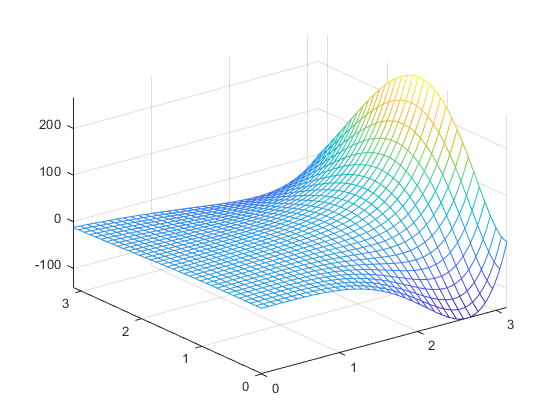

fmesh(g(x,y),[0,pi 0, pi])

Do definiowania symbolicznych wyrażeń liczbowych służy funkcja [sym()](https://www.mathworks.com/help/symbolic/sym.html).

A = sym(1/2) 

$$A = \frac{1}{2}$$

B = sym(1/3)

$$B = \frac{1}{3}$$

C = A+B

$$C = \frac{5}{6}$$

Aby zmienić liczbę symboliczną na reprezentację zmiennoprzecinkową należy użyć funkcji [vpa()](https://www.mathworks.com/help/symbolic/vpa.html).

D = vpa(C)

$$D = 0.83333333333333333333333333333333$$

## Macierze symbolicznych zmiennych skalarnych

Tworzenie macierzy i wektorów złożonych ze zmiennych skalarnych wykonuje się identycznie jak dla zwykłych zmiennych. Ponadto obowiązują to identyczne zasady jak w przypadku zwykłych macierzy.

M1 = [a x; b c]

$$M1 = \left(\begin{array}{cc} a & x\\ b & c \end{array}\right)$$

v = [A;B]

$$v = \left(\begin{array}{c} \frac{1}{2}\\ \frac{1}{3} \end{array}\right)$$

w = M1*v % mnożenie macierzy przez wektor

$$w = \left(\begin{array}{c} \frac{a}{2}+\frac{x}{3}\\ \frac{b}{2}+\frac{c}{3} \end{array}\right)$$

sum(w) % obliczenie sumy elementów otrzymanego wektora

$$ans = \frac{a}{2}+\frac{b}{2}+\frac{c}{3}+\frac{x}{3}$$

W celu [utworzenia macierzy zmiennych skalarnych](https://www.mathworks.com/help/symbolic/create-symbolic-matrices.html) można użyć funkcji sym(), do której jako pierwszy argument przekazana jest nazwa zmiennej, a jako drugi przekazane są wymiary macierzy lub poprzez użycie polecenia syms, w którym po nazwachzmiennych występuje wektor wymiarów tworzonej macierzy.

M = sym('M', [2 2])

$$M = \left(\begin{array}{cc} M_{1,1} & M_{1,2}\\ M_{2,1} & M_{2,2} \end{array}\right)$$

det(M) % obliczenie wyznacznika

$$ans = M_{1,1}\,M_{2,2}-M_{1,2}\,M_{2,1}$$

syms A [2 2]
A

$$A = \left(\begin{array}{cc} A_{1,1} & A_{1,2}\\ A_{2,1} & A_{2,2} \end{array}\right)$$

## Symboliczne zmienne macierzowe

Symboliczne zmienne macierzowe reprezentują macierze (ale nie są macierzami elementów symbolicznych). Tworzy się je przy pomocy polecenia syms, w którym podaje się nazwę i rozmiar macierzy a następnie słowo kluczowe matrix. Zmienne takie wykorzystuje się do zapisu operacji macierzowych, ale bez operowania bezpośrednio na ich elementach (elementy macierzy nie są wypisywane domyślnie). Oczywiście wyświetlenie poszczególnych elementów takiej macierzy jest możliwe przy użyciu zwykłych operatorów. 

syms A B [2 2] matrix
C = A * B.' % wyrażenie macierzowe

$$C = A\,B^{T}$$

C(1,1) % pokaż element macierzy o indeksie (1,1)

$$ans = A_{1,1}\,B_{1,1}+A_{1,2}\,B_{1,2}$$

C(:,:) % wyświetl wszystkie elementy wynikowej macierzy

$$ans = \left(\begin{array}{cc} A_{1,1}\,B_{1,1}+A_{1,2}\,B_{1,2} & A_{1,1}\,B_{2,1}+A_{1,2}\,B_{2,2}\\ A_{2,1}\,B_{1,1}+A_{2,2}\,B_{1,2} & A_{2,1}\,B_{2,1}+A_{2,2}\,B_{2,2} \end{array}\right)$$